n=0:100;
f=40;
sig=1/5*sin(2*pi*n/f) + 1/5*sin(2*pi*n/(2*f)) + 1/5*sin(2*pi*n/(7*f)) + 1/5*sin(2*pi*n/(9*f))+ 1/5*sin(2*pi*n/(6*f));
ZeroPadSig=[sig zeros(1,100)];
zn=0:length(ZeroPadSig)-1;

figure;
ax = gca

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


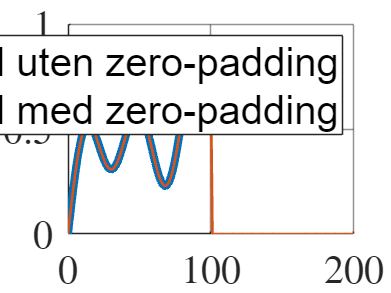

grid;
ax.GridAlpha=0.5;
ax.FontSize=30;
set(ax.YLabel,'rotation',0);
ax.TickLabelInterpreter='latex';
hold on;
plot(n,sig,'LineWidth',6)
plot(zn,ZeroPadSig,'-','LineWidth',2);

legend("Signal uten zero-padding","Signal med zero-padding",'FontSize',30)